clear
clc

%import the video
filepath = "SCDD10_sandDLC_mobnet_100_KRAT DATA WITH NEW DATAJun23shuffle1_700000_filtered_labeled.mp4"

filepath = "SCDD10_sandDLC_mobnet_100_KRAT DATA WITH NEW DATAJun23shuffle1_700000_filtered_labeled.mp4"

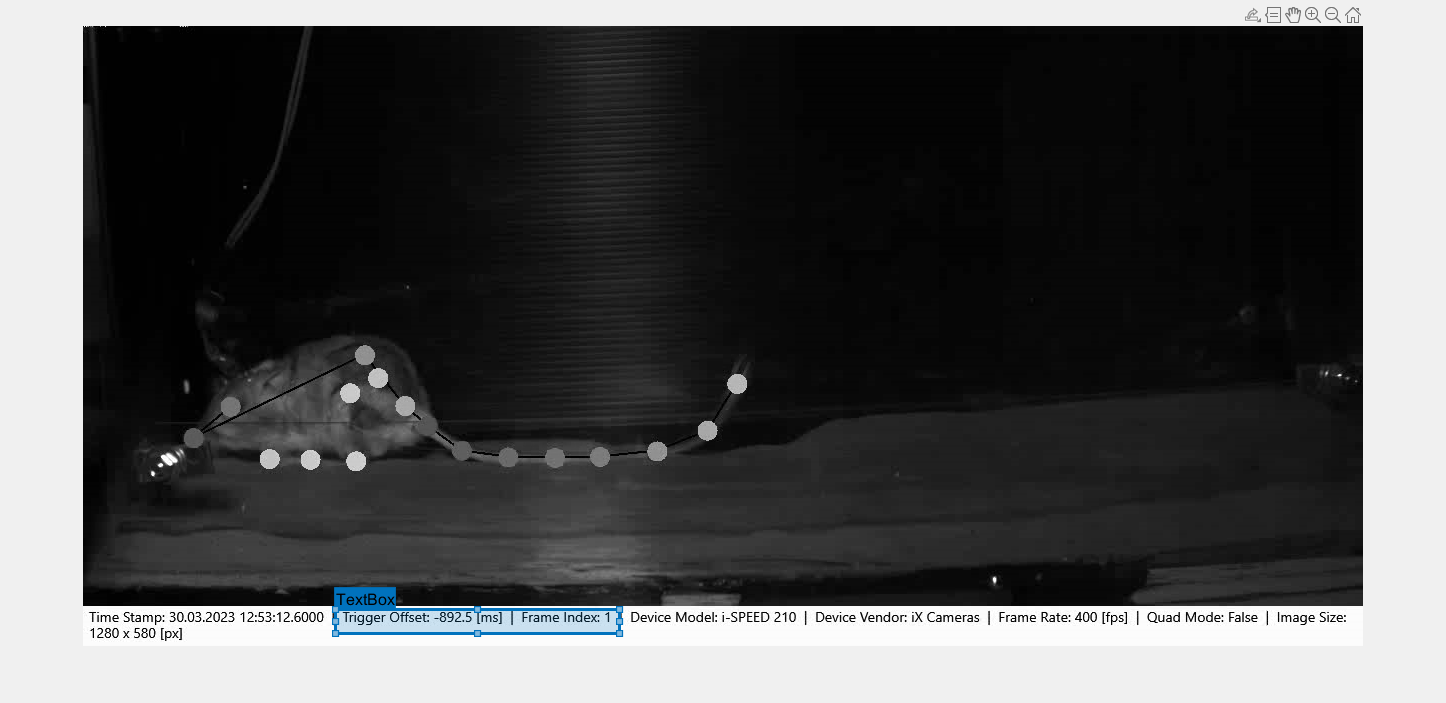

roi =   Rectangle with properties:

         Position: [253.0000 584 284.0000 24]
    RotationAngle: 0
      AspectRatio: 0.0845
            Label: 'TextBox'
            Color: [0 0.4470 0.7410]
           Parent: [1×1 Axes]
          Visible: on
         Selected: 0

  Show all properties


video = VideoReader(filepath);

colorFrame = read(video,1);
grayImage = rgb2gray(colorFrame);

figure;
imshow(grayImage)
%roi = round(getPosition(impact))
roi = drawrectangle('Label', 'TextBox')

roi_pos = round(roi.Position);